# Immisicble two-phase flow drainage in a subsurface reservoir - example 1 

In this tutorial two-dimensional immiscible two-phase flow drainage of oil by water injection is simulated. Permeability and porosity distributions are extracted from the first layer of the geological model of SPE10 comparative solution project. 

This script is divided into four steps:

- Permeabiiity and porosity data are loaded from disk files and plotted. Next, we verify that these variables are correlated as expected.

- Setup other simulation data, such as wells positions, flow rates, fluid properties, initial pressure and saturation conditions, the time stepping parameters, and the nonlinear solver options.

- Run the time simulation loop involving a sequential solution procedure between pressure and saturation equations which are solved both implicitly.

- Post-processing of the numerical results by plotting the spatial distributions of simulated pressure and saturation at the final time. 

## Load and plot the petrophysical (permeability and porosity) data

Let's construct the computational domain:

% Domain size along X, Y & Z directions
dom = RecDomain([365.76,670.56,0.6096]);
Dx = dom.Lx; Dy = dom.Ly; Dz = dom.Lz;

Set the number of cells along X, Y, and Z directions; 

Grid.Nx = 60;   Grid.Ny = 220;   Grid.Nz = 1; 
Nx = Grid.Nx;   Ny = Grid.Ny;    Nz = Grid.Nz; 

Set grid sizes along each direction:

Grid.hx = (Dx/Nx);
Grid.hy = (Dy/Ny);
Grid.hz = (Dz/Nz);

The, total number of gridblocks: 

Grid.N = Grid.Nx*Grid.Ny*Grid.Nz;
N = Grid.N;

Set Grid data: 

Grid.V = (Dx/Nx)*(Dy/Ny)*(Dz/Nz);                        % Cell volumes
Grid.K = 1.4e-11.*ones(3,Nx,Ny,Nz);                      % Unit-Darcy permeability
Grid.compr = 4.4e-10.*ones(Grid.Nx,Grid.Ny,Grid.Nz);     % compressibility

Load porosity data from a saved mat file: 

load '..\data\spe_layer1_phi.mat' phi_layer;
phi = phi_layer; clear phi_layer;
phi = max (phi(:), 1e-3); % to avoid zero porosity cells
Grid.por = reshape(phi',Nx,Ny,Nz); 

Load permeability data from a saved mat file: 

load '..\data\spe_layer1_perm.mat' perm_layer;
Grid.K = perm_layer*9.869232667160130e-13;
Grid.K = reshape(Grid.K',3,Nx,Ny,Nz); 

Draw porosity and permeability maps. Notice that the considered permeability tensor is diagonal, so we plot herein only K along x direction but in log10 scale to depict the extent of its spreading in logarithmic scale.

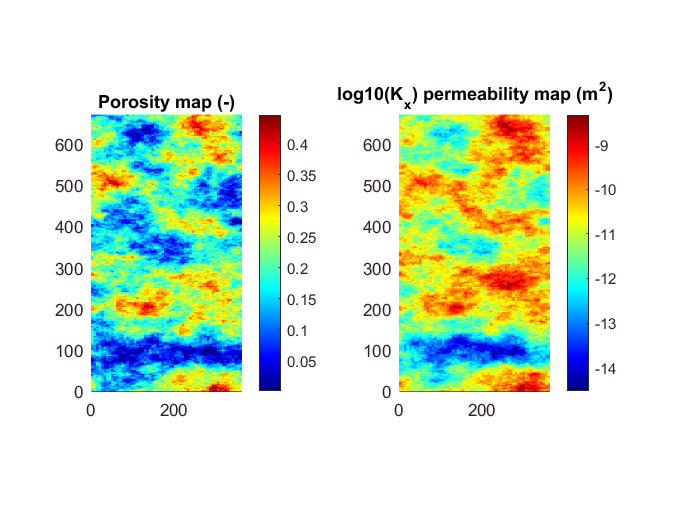

G = cartGrid(0:Dx/Nx:Dx, 0:Dy/Ny:Dy);

figure;
colormap(jet(16));

subplot(1,2,1);
PlotCellData(G, phi, 'EdgeColor','none');
axis tight equal; colorbar, title('Porosity map (-)');

subplot(1,2,2);
PlotCellData(G, reshape(log10(Grid.K(1,:,:,:)),N,1), 'EdgeColor','none');
axis tight equal; colorbar, title('log10(K_x) permeability map (m^2)');

clear phi;

Now, we check if the permeability and porosity fields ara correlated somehow. First, let's start with the first component of the diagonal permability tensor, Kx:

corrcoef(reshape(log10(Grid.K(1,:,:,:)),N,1),reshape(Grid.por(:,:,:),N,1))

ans =     1.0000    0.8819
    0.8819    1.0000


Off-diagonals of the correlation matrix are high positive values indicating a good positive correlation between the two variables. Let's now do the same thing for the y and z components of the permeability to conclude on their correlation with the porosity. 

corrcoef(reshape(log10(Grid.K(2,:,:,:)),N,1),reshape(Grid.por(:,:,:),N,1))

ans =     1.0000    0.8819
    0.8819    1.0000


corrcoef(reshape(log10(Grid.K(3,:,:,:)),N,1),reshape(Grid.por(:,:,:),N,1))

ans =     1.0000    0.7651
    0.7651    1.0000


## Setup simulation data

Add injection / production wells and their rate. Four production wells are placed at the corners with Qt/4 pumping rates and one injection well at the center of the domain with an injection rate equal to Qt: 

% Cell-centered injection/production flow rates
Total      = 25/3600;
Qw         = zeros(N,1);
Qw([1 N])  = [-Total/4 -Total/4];
Qw(Nx)     = -Total/4;
Qw(N-Nx+1) = -Total/4;
index      = (Nx*(Ny-1))/2;
Qw(index)  = Total;

Initialize two fluids saline water and oil:

% fluid properties units: density (Kg/m^3), viscosity (Pa.s), residual saturation ()
oil   = Fluid('Oil',      [1200, 3e-3,  0.3]);   % resident fluid
brine = Fluid('Saltwater',[1030, 5e-4, 1e-2]);   % injected fluid

Initialize fluid 'global' pressure in the computational domain to 100 bars and the initial saturation of brine (injected phase) to its residual value (i.e. 1e-2)

P = 100e5.*ones(Nx,Ny,Nz);
S = brine.Sr.*ones(N,1);

Define time stepping parameters including total simulation time, T, the number of time steps, nt, and the constant time step, dt (in seconds):

day = 3600*24;                     % seconds/day
T   = 50*day;                      % 30 days
nt  = 25;                          % number of time steps
dt  = T/nt;                        % time step

Setup options for the inner Newton-Raphson iterations:

opt.tol     = 1e-6;
opt.maxiter = 100;

## Run the time simulation loop - Sequential implicit solution

Now, start the time loop involving sequential solution of the governing global pressure equation and the nonlinear non-wetting phase saturation equation formulated in fractional form. The pressure and saturation solvers are both implicit implying an unconditional stability regardlless of the magnitude of the selected time step. 

The pressure equation, neglecting the gravitational term is given as:


$$\phi c_t \frac{\partial P}{\partial t} = \nabla.[K \lambda_t \nabla p] + \frac{q_w}{\rho_w}$$
 

where $c_t$ is the total compressibility, $\phi$ is the rock porosity, $P$ is the fluid pressure, $\lambda_t = \lambda_o + \lambda_w$ is the total mobility as the sum of oil and water mobilities. A fluid phase mobility $\lambda_l$ is the ratio of its relative permeability $k_{r,l}$ to its viscosity $\mu_l$. $q_w$ is the water injection/withdawal term and $\rho_w$ is the density of the water phase.

The saturatin equation in this case is a nonlinear diffusion-convection like equation for the water phase given as:


$$\phi \frac{\partial S_w}{\partial t} = - \nabla . (f_w \textbf{u}) + \frac{q_w}{\rho_w}$$


where $S_w$ is the water phase saturation, $f_w$ is the saturation-dependent fractional flow function for the water phase, $\textbf{u} = \textbf{u_{w} + \textbf{u_o}$ is the total velocity (i.e. the sum of fluid velocities of each phase). 

 Herein, the pressure solver is linear but requires successive updating of the total mobility of both fluid phases which is the task of `TwoPhasePressure `function. It just wraps the two-point flux approximation solver (in `TPFA` function) such that $\lambda_t (S_w)$ is updated from tha water saturation spatial distribution calculated in the previous time step and multiplied by the intrinsic permeability tensor just before the pressure solve. 

The saturation solver uses an adaptive time steeping procedure combined to an inner Newton-Raphson (NR) iteration loop. During the inner NR loop the sparse system Jacobian matrix $\textbf{J} = \frac{dF(S_w)}{dS_w}$ is evaluated analytically to accelerate the algorithm convergence. If the NR iteration fails the current time step is subdivided (i.e. the number of sub-steps is multiplied by 2) and the whole time step is repeated from the beginning point. The latter mechanism is called back-stepping. The NR local failure is due to either (i) an insuffisant or small number of allowed maximal iterations to achieve the required accuracy so when setting the NR options the user should keep a good balance between the maxiter and tol options; (ii) second, to a high or very difficult level of prescribed accuracy which cannot be achived for badly preconditioned problems so the absolute tolerance should be kept to reasonable values (in practice values between 1e-3 and 1e-4 are suggested); (iii) and finally, when the selected global time step results in large local pressure jumps the same time step is inappropriate for the saturation solver implying a smaller time step advancement of the saturation time marching to 'absorp' the numerical shock caused by the large pressure jump. 

In general, this adaptive time stepping strategy is effective in practice. Very often the algorithm starts with smaller saturation time steps at the begining of the simulation when initial conditions are far from the expected solution in the first time step. This sub-time step will gradually increase in the next time steps if there is no abrupt change in the boundary conditions (i.e. wells pumping or production schedule) or materials and fluids properties for problems coupled to external processes. 

Let's now simulate this two-pahse oil drainge problem:

tic;              % start timing the time marching loop
for t=1:nt
   fprintf('\n'); 
   fprintf('Solving two-phase flow problem. Time = %f days\n', t*dt/day);
   
   % call TPFA flow solver adapted to two-phase flow 
   [P,V] = TwoPhasePressure(Grid,S,brine,oil,Qw,P,dt); 
   
   % solve for brine saturation 
   S = ImplicitSaturation(Grid,S,brine,oil,V,Qw,dt,opt);

end

Solving two-phase flow problem. Time = 2.000000 days


...........
Converged in 12 time sub-steps and 4924 Newton-Raphson iterations


Solving two-phase flow problem. Time = 4.000000 days


....
Converged in 5 time sub-steps and 84 Newton-Raphson iterations


Solving two-phase flow problem. Time = 6.000000 days


....
Converged in 5 time sub-steps and 99 Newton-Raphson iterations


Solving two-phase flow problem. Time = 8.000000 days


....
Converged in 5 time sub-steps and 98 Newton-Raphson iterations


Solving two-phase flow problem. Time = 10.000000 days


..
Converged in 3 time sub-steps and 36 Newton-Raphson iterations


Solving two-phase flow problem. Time = 12.000000 days


..
Converged in 3 time sub-steps and 31 Newton-Raphson iterations


Solving two-phase flow problem. Time = 14.000000 days


..
Converged in 3 time sub-steps and 32 Newton-Raphson iterations


Solving two-phase flow problem. Time = 16.000000 days


.
Converged in 2 time sub-steps and 15 Newton-Raphson iterations


Solving two-phase flow problem. Time = 18.000000 days


.
Converged in 2 time sub-steps and 14 Newton-Raphson iterations


Solving two-phase flow problem. Time = 20.000000 days


.
Converged in 2 time sub-steps and 16 Newton-Raphson iterations


Solving two-phase flow problem. Time = 22.000000 days


Converged in 1 time sub-steps and 9 Newton-Raphson iterations


Solving two-phase flow problem. Time = 24.000000 days


Converged in 1 time sub-steps and 7 Newton-Raphson iterations


Solving two-phase flow problem. Time = 26.000000 days


Converged in 1 time sub-steps and 5 Newton-Raphson iterations


Solving two-phase flow problem. Time = 28.000000 days


Converged in 1 time sub-steps and 7 Newton-Raphson iterations


Solving two-phase flow problem. Time = 30.000000 days


Converged in 1 time sub-steps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 32.000000 days


Converged in 1 time sub-steps and 7 Newton-Raphson iterations


Solving two-phase flow problem. Time = 34.000000 days


Converged in 1 time sub-steps and 10 Newton-Raphson iterations


Solving two-phase flow problem. Time = 36.000000 days


Converged in 1 time sub-steps and 7 Newton-Raphson iterations


Solving two-phase flow problem. Time = 38.000000 days


Converged in 1 time sub-steps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 40.000000 days


Converged in 1 time sub-steps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 42.000000 days


Converged in 1 time sub-steps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 44.000000 days


Converged in 1 time sub-steps and 8 Newton-Raphson iterations


Solving two-phase flow problem. Time = 46.000000 days


Converged in 1 time sub-steps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 48.000000 days


Converged in 1 time sub-steps and 6 Newton-Raphson iterations


Solving two-phase flow problem. Time = 50.000000 days


Converged in 1 time sub-steps and 6 Newton-Raphson iterations


toc;

Elapsed time is 33.512132 seconds.


From the convergence output we notice that this  sequential solution algorithm went very smmothly. There was a difficulty to converge in the first time step because it seems that a 2 days time step was very large for the saturation hence the time step was subdivided 12 time resulting in an effective saturation time step $dt_s^1$equal to 42 seconds as calculated below

dt_s(1) = 2*day/2^12

dt_s = 42.1875

this internal saturation time step gradually increases to 1.5 hour,  6 hours, 12 hours and finally 2 days starting from 22 days after the simulation startup. So, afterwards the pressure and saturation time steps becomes equal meaning that the saturation extent of the plume becomes significant enough to amortize the pressure jumps. 

**Post-processing of the numerical solution - mapping mode**

Since the main simulated variales are pressure $P$ and water saturation $S_w$ we will plot them directly using the supplied functions which make use of MATLAB's excellent built-in graphics capabilities whithout writing the results into text or binary files in a required format and loading them back into an external third-party post-processing software. So, with just a fewer command we get instantly the results ready for interpretation freeing the modeller from all intermediate tasks and hence speeding the data-processing-simulation-post-processing workflow significantly. 

We will use here the routine `PlotCellData` to produce the figures in 'mapping mode' where each cell in the grid is plotted with a constant color corresponding to a linearly interpolated value between the *upper* and lower colors in the used colormap. The colormap fits the range between the maximal and minimal values detected in the data array.  

The `figure` command without any argument opens a new MATLAB figure (or axis in Matlab terminology) so that the previously opened figures are preserved and the next drwing commnds will be placed in this new figure. The colormap command is optionally called before the drawing commands to choose among the available color maps, here we choose the `jet` colormap with 256 colors distributed between blue and red. 

figure; 
colormap(jet(256));

Next, we plot the pressure after convertion to bar units. We call first subplot command to specify that we want to make a plot matrix with 1 row and 2 columns in the target figure. The last argument in the subplot command is the active subplot to which the next plotting commands are directed. The `PlotCellData` function takes additional property-value pairs (à la Matlab), this options are those supported by the low level patch command. To explore all these options type `help patch` command or search for patch in the help system to get into this page.  Here the '`EdgeColor`' property specifies the color of the underlying mesh edges, by setting this property to '`none`' the mesh edges will be hidden. In this example the grid is so dense so drawing the mesh edges will obscure the reulting figures but in applications where a coarse grid is used tweaking this property may be skipped by the user.

% plot fluid pressure 
subplot(1,2,1);
PlotCellData(G, P(:)*1e-5, 'EdgeColor','none');

By default Matlab plots fit to the rectangular window inside which they're displayed. A good idea herein is to call the `axis` command adjust the X and Y axis scales to be `equal`. Likewise, `tight` wil readjust the plot to fit at best the window after axis scaling. Finally, we decorate the plot with a `colorbar` and a custom `title` string. 

axis tight equal; colorbar, title('Pressure [bar)]');

We follow the same previous steps to plot the water saturation distribution. 

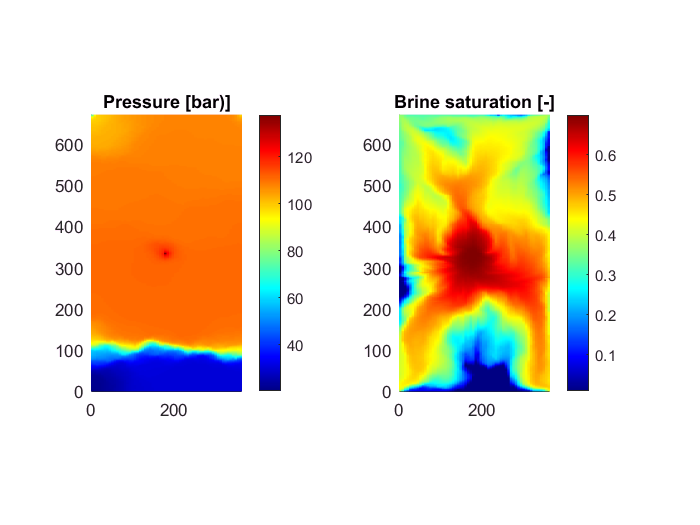

% plot brine saturation 
subplot(1,2,2);
PlotCellData(G, S(:), 'EdgeColor','none');
axis tight equal; colorbar, title('Brine saturation [-]');

**Post-processing of the numerical solution - contouring mode**

Presenting the results in mapping mode is most natural when working will cell-centered discretization methods. It has also the advantage to appreciate the dispersion of the saturation plume as seen in the right plot of the above figure. But, it has few limitations. For instance, the gradient of the variables cannot be easily appreciated, the presentations graphics quality may deteriorate when saving the figure into raster file formats, and in general such presentation mode is not suitable for explanation to non-specialists such as managers and decision makers. 

Another presentation mode which is quite popular in all fields of geoscinces in contouring. The target variable iso-values are traced by a general purpose algorithm to contour the data. Such presentation mode is also supported by basic Matlab routines such as `contour`, `contourc`, `contourf` and `contour3`. We will use `PlotContourData` function which is a simple wrapper to contourf to plot filled contour plots. This function arguments are similar to `PlotCellData` function except for the optional arguments are property-value pairs which are compatible with those of the `contourf` command. 

So, a figure made from two contour plots of water pressure and saturation is constructed as follows:

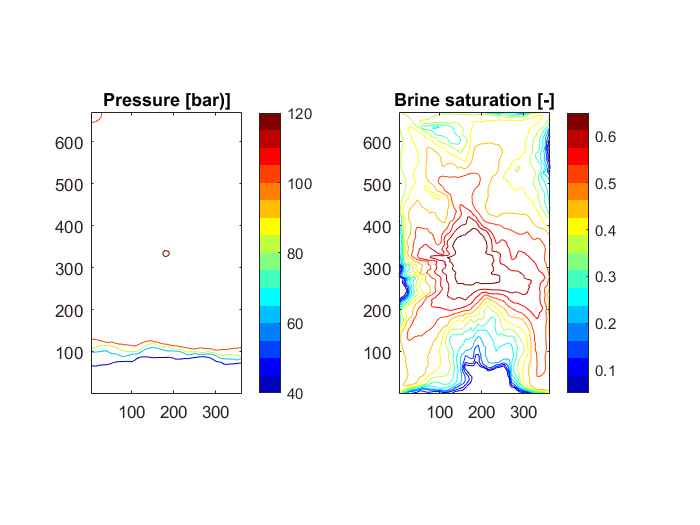

figure;
opts.fill = 'off';
subplot(1,2,1);
PlotContourData(G, P(:)*1e-5,opts,'LevelList',20:20:140);
colormap(jet(16));
axis tight equal; colorbar, title('Pressure [bar)]');
subplot(1,2,2);
PlotContourData(G, S(:),opts,'LevelList',0:0.05:0.7);
axis tight equal; colorbar, title('Brine saturation [-]');

To better understand the spatial distribution of brine saturation we also plot the probability distribution of this simulated variable reflecting the saturation volumetrics in the reservoir. To do that we call the histogram command for $S$ variable with 7 bins as a second argument and '`probability`' value for the '`Normalization`' option. This means that the height of each bar is the relative number of cell-centered saturations, (number of saturations in bin / total number of saturations). The sum of the bar heights is obvously equal to 1.

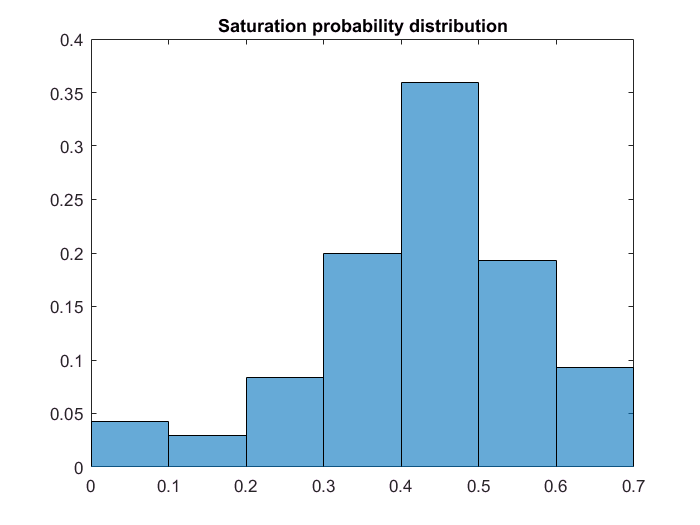

figure;
histogram(S,7,'Normalization','probability');
title('Saturation probability distribution');

Arround 35% of the reservoir volume is filled with water saturations between 0.4 and 0.5 while arround 75% of the reservoir volume is filled with water saturations between 0.3 and 0.6 which are clearly the dominant modes of saturations after 50 days of drainage. 

## Conclusions

In merely less than 90 lines of Matlab scripting commands (including blank and comment lines) we were able in this tutorial to: 

- Read petrophysical distrbutions from disk files, plot, and analyze them.

- Setup auxilliary simulation data 

- Run the time simulation loop for the two-phase flow drainge problem involving a sequential simulation procedure and analyze the convergence behavior. 

- Post-process the numerical solution using mapping and contouring modes, then analyze the spatial distribution of water saturation after 50 days of oil drainage. 

All these steps consume a total CPU time less than 1 min in a comodity PC. With such scripting methodology the time traditionally involved in file transfer between pre-processing, simulation, post-processing as in existing workflows and software is minimal enabling the analyst to gain in problem understanding rather than spending a significant project timeframe in useless data manipulation tasks.